# Example: Fabry-Perot Directivity

This example demonstrates how to model the directivity of Fabry-Perot ultrasound sensors using the `FabryPerotSensor` class. The `FabryPerotSensor` class is a child class of `ElasticMatrix` and is an example of how the `ElasticMatrix` toolbox may be expanded. For more information about the Fabry-Perot ultrasound sensor and modeling process see [1,2].

[1] Ramasawmy, D. R., et al. "Analysis of the Directivity of Glass Etalon Fabry-Pérot Ultrasound Sensors." IEEE transactions on ultrasonics, ferroelectrics, and frequency control (2019). 

[2] Cox, Benjamin T., and Paul C. Beard. "The frequency-dependent directivity of a planar Fabry-Perot polymer film ultrasound sensor." IEEE transactions on ultrasonics, ferroelectrics, and frequency control, (2007).

## Initialize a `FabryPerotSensor` Object

The `FabryPerotSensor` class is initialized with a `Medium` object. For this example an air-backed glass cover-slip sensor is defined.

% Geometry of the Fabry-Perot sensor:
my_sensor_medium = Medium('water', Inf, 'glass', 175.9e-6, 'air', Inf);

% Initialize the FabryPerotSensor class:
my_sensor = FabryPerotSensor(my_sensor_medium);

## Setting Calculation Parameters

`FabryPerotSensor` inherits `ElasticMatrix`, therefore all of the methods available to `ElasticMatrix` are also available to `FabryPerotSensor`. Generally, the Fabry-Perot directivity is calculated over a range of angles and frequencies.

% Set a range of angles and frequencies:
my_sensor.setAngle(linspace(0, 45, 150));
my_sensor.setFrequency(linspace(0.1e6, 50e6, 150));

Set the interrogating beam spot diameter of the Fabry-Perot sensor:

my_sensor.setSpotDiameter(10e-6);

Set the interrogating laser beam profile of the Fabry-Perot sensor, this can be either `'collimated'` or `'gaussian'`:

my_sensor.setSpotType('gaussian');

Set the locations of the Fabry-Perot mirrors, these are defined as the location of the interfaces, for example between layer index 1 and layer index 2 is interface 1 and between layer index 2 and layer index 3 is interface 2:

interface_1 = 1;
interface_2 = 2;
my_sensor.setMirrorLocations([interface_1, interface_2])

ans = ===============================================================
   FabryPerotSensor  
    Filename:   
  
 
    Properties to set:
 
      property      miniumum    maximum    length      units   
    ____________    ________    _______    ______    __________
    'frequency'     [0.1000]     [50]       150      '[MHz]'   
    'angle'         [0.0100]     [45]       150      '[degree]'
    'phasespeed'    []           []           0      '[m/s]'   
    'wavenumber'    []           []           0      '[1/m]'   
 
    Properties to calculate:
 
            property             calculated
    _________________________    __________
    'partial_wave_amplitudes'      false   
    'x_dis

## Calculating Directivity

Use the .`calculateDirectivity` method to calculate the directivity.

% Calculate the directivity:
my_sensor.calculateDirectivity;

... calculating directivity ...
... calculating matrix method ... 
... frequency-angle calculation ...
... finished calculating matrix method ... 
... finished calculating directivity ...


## Plotting Directivity

There are a number of different ways to plot the modeled directivity. 

% On the decibel scale:
figure_handle(1) = my_sensor.plotDirectivity('decibel');

... plotting directivity ...


% Plot the frequency-response: 
figure_handle(2) = my_sensor.plotDirectivity('normal');

... plotting directivity ...


% Plot the directivity normalized to the maximum of the
% frequency-response:
figure_handle(3) = my_sensor.plotDirectivity('normalise');

... plotting directivity ...


% Plot the directivity on a linear scale:
figure_handle(4) = my_sensor.plotDirectivity('linear');

... plotting directivity ...


% Plot the wrapped phase of the directivity:
figure_handle(4) = my_sensor.plotDirectivity('linear');

... plotting directivity ...


% Plot all of the above:
figure_handle(6:10) = my_sensor.plotDirectivity;

... plotting directivity ...


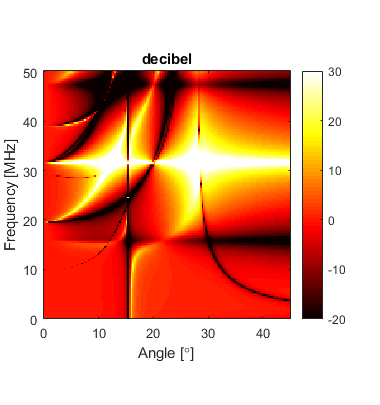

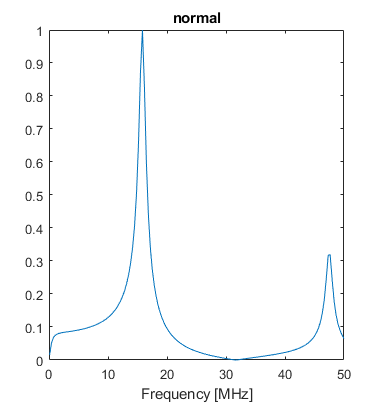

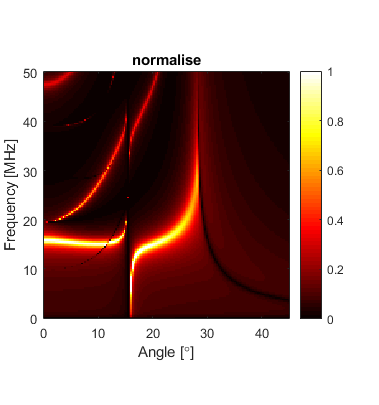

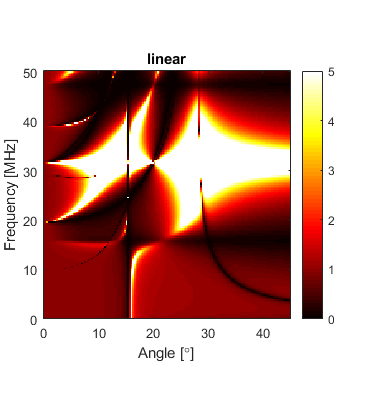

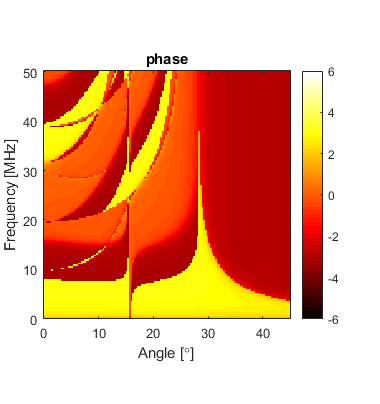

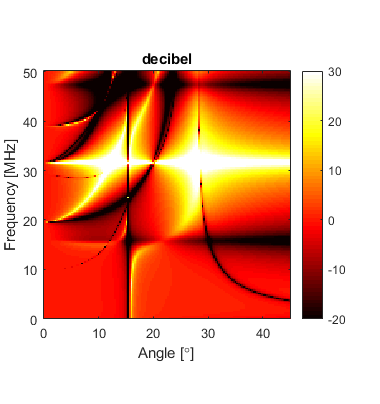

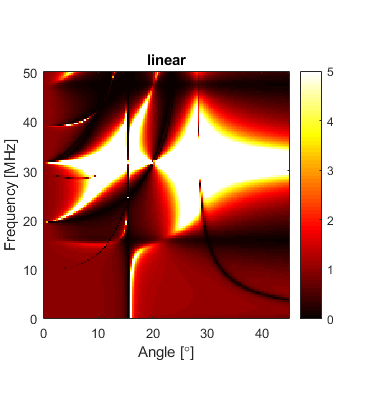

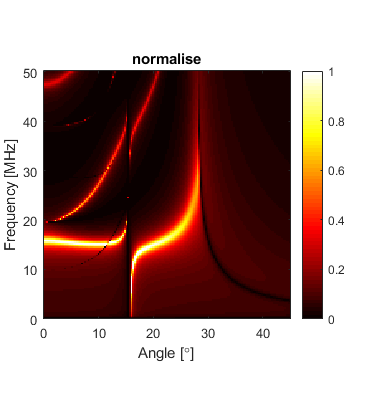

... distributing figures ...


% Distribute the figures on the screen:
sfg;

## Getting Directivity Data

To process the directional response in a different way the complex directivity can be taken using the .`getDirectivity` method with these input arguments:

- `'raw'` - return complex directivity 

- `'real'` - imaginary part of obj.directivity 

- `'imag'` - real part of obj.directivity 

- `'phase'` - phase of obj.directivity 

- `'abs'` - absolute value of the directivity 

- `'linear'` - normalied to normal incidence response 

- `'decibel'` - plots the previous option on a decibel scale 

- `'normalise'` - normalised to maximum value of normal incidence 

- `'normal'` - normal incidence response

% For example to get the directivity normalized between 0 and 1:
directivity_normalised = my_sensor.getDirectivity('normalise');

## Calculating Dispersion Curves

Here the dispersion curves are calculated for a glass plate in a vacuum which is a good approximation for this sensor. The points for each mode are converted from phase-speed to an angle using the bulk wave-speed of the first layer in the sensor geometry (water) and plotted on a map of directivity.

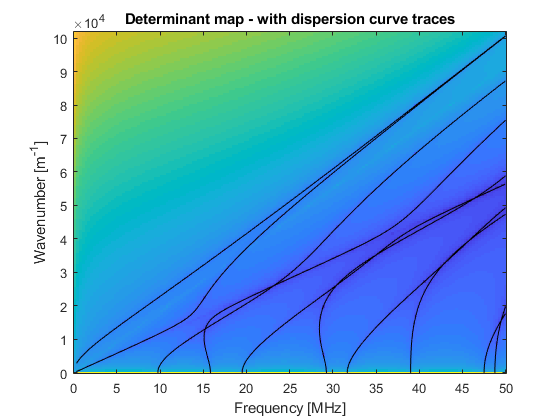

... calculating dispersion curves ...
... finished calculating dispersion curves ...


% Geometry of the glass plate:
my_medium = Medium('vacuum', Inf, 'glass', 175.9e-6, 'vacuum', Inf);
my_model = FabryPerotSensor(my_medium);

% Set properties:
my_model.setFrequency(linspace(0.1e6, 50e6, 150));

% Calculate dispersion curves:
my_model.calculateDispersionCurves;

% Plot the directional response:
figure_handle_dispersion = my_sensor.plotDirectivity('normalise');

... plotting directivity ...


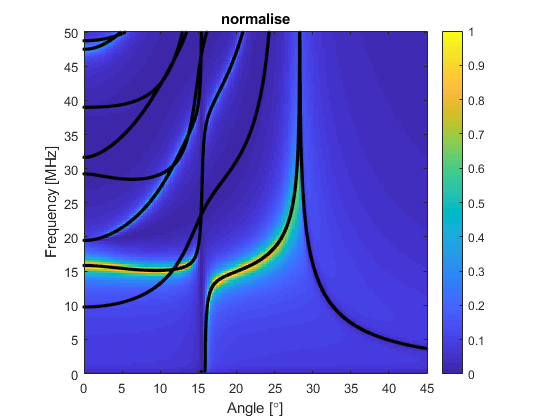

colormap parula
hold on

% Loop over each guided mode curve:
for idx = 1:length(my_model.dispersion_curves)
    
    % Retrieve dispersion curve points:
    cph_points  = my_model.dispersion_curves(idx).c;
    f_points    = my_model.dispersion_curves(idx).f;
    
    % Convert phase-speed to angle using the sound-speed in the first layer
    % (water):
    angle_points = real(asin(1480 ./ cph_points)) * 180 / pi;
    
    % Plot dispersion points over a directivity map:
    plot(angle_points, f_points / 1e6, 'k.')

end
xlim([0 45])